# IIR FIlters

- infinite impulse response filter

- use 2 sets of coefficients, one for values of original signal, one for values of filtered signal

### Butterworth filter

sample_rate = 1024;
nyquist = sample_rate/2;
freq_range = [20 45];

% 4th order filter 
[kernel_b,kernel_a] = butter(4, freq_range/nyquist);
% power spectrum
kernel_power = abs(fft(kernel_b)).^2;
% hz is always from - to nyquist in len(kernel)/2 bins
hz_vals = linspace(0, nyquist, floor(length(kernel_b)/2)+1);

- Plot the kernel

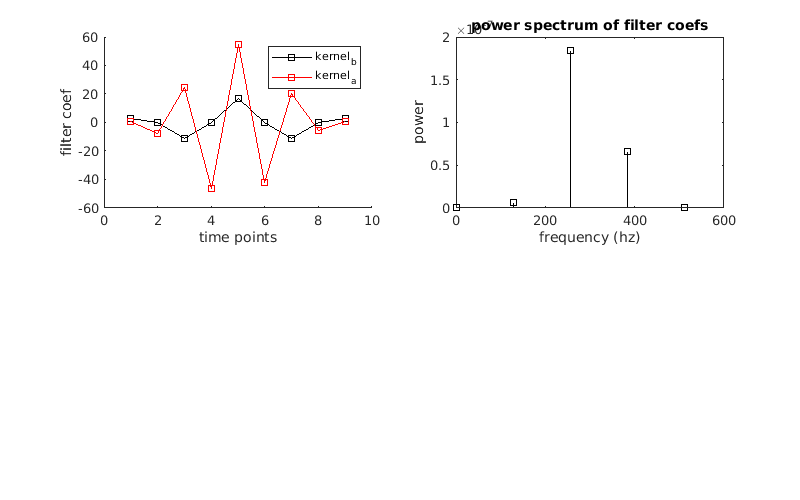

f1 = figure(1); clf;
f1.Position = [0 0 800 500];
subplot(221);
hold on;
plot(kernel_b*1e5, 'ks-');
plot(kernel_a, 'rs-');
xlabel("time points");
ylabel("filter coef");
legend(["kernel_b", "kernel_a"]);
hold off;

subplot(222);
stem(hz_vals, kernel_power(1:length(hz_vals)), 'ks-');
xlabel("frequency (hz)");
ylabel("power");
title("power spectrum of filter coefs");